clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


FPs = obj.MixedFP;
beh = obj.BehavTable;

session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");

HD = obj.HDSorted; HDPDF = obj.HDPDF; HDCDF = obj.HDCDF;
RT = obj.RTSorted; RTPDF = obj.RTPDF; RTCDF = obj.RTCDF;
MT = obj.MTSorted; MTPDF = obj.MTPDF; MTCDF = obj.MTCDF;


## Hold duration and reaction time

rt_pd_max = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), RTPDF.Control, RTPDF.Chemo)));
rt_pd_ylim = ceil(rt_pd_max);


[~, hd_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), HD.Control, HD.Chemo);
hd_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), HD.Control, HD.Chemo);

[~, rt_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), RT.Control, RT.Chemo);
rt_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), RT.Control, RT.Chemo);


hd_categories = [0 .25 .5 2];
rt_categories = [.25 .5 2];

hd_p_chi2 = zeros(3, 2);
rt_p_chi2 = zeros(3, 2);
hd_p_chi2_sub = cell(3, 2);
rt_p_chi2_sub = cell(3, 2);
for fp = 1:3
    for p = 1:2
        [hd_p_chi2(fp, p), ~, hd_p_chi2_sub{fp, p}] = Chi2Test_Distr({HD.Control{fp, p}-FPs(fp), HD.Chemo{fp, p}-FPs(fp)}, hd_categories);
        [rt_p_chi2(fp, p), ~, rt_p_chi2_sub{fp, p}] = Chi2Test_Distr({RT.Control{fp, p}, RT.Chemo{fp, p}}, rt_categories);
    end
end

alpha = [.05 .01 .001];
alpha_hd = alpha ./ length(hd_categories);
alpha_rt = alpha ./ length(rt_categories);

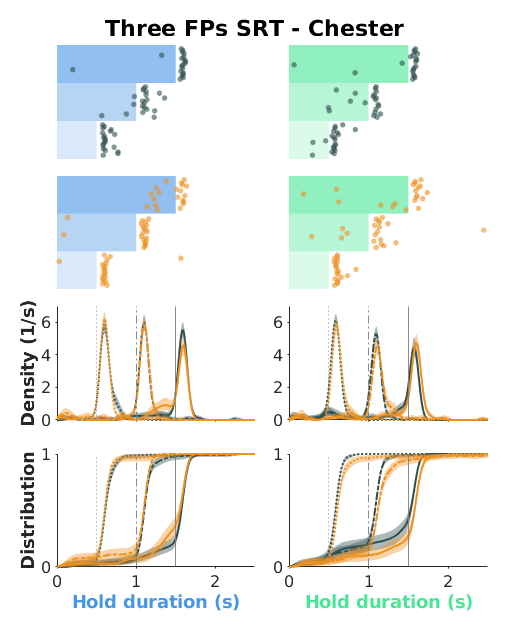

hd_pd_max = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), HDPDF.Control, HDPDF.Chemo)));
hd_pd_ylim = ceil(hd_pd_max);

n_show = 20;

fig_hd = figure(31); clf(fig_hd);
set(fig_hd, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 9 11.2], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_hd, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_w = 3.5; ax_h = 2;
ax_w_sep = .6; ax_h_sep = .3;

ax_w_dist = ax_w + ax_w_sep;
ax_h_dist = ax_h + ax_h_sep;

% LEFT
% show trials
ax_s_control_l = axes(fig_hd, "Units", "centimeters", "Position", [1 1.5+3*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
show_trials(ax_s_control_l, HD.Control(:,1), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortL, 'MarkerColor', GPSColor.Control, 'MarkerSize', 8);
set(ax_s_control_l, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');

ax_s_chemo_l = axes(fig_hd, "Units", "centimeters", "Position", [1 1.5+2*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
show_trials(ax_s_chemo_l, HD.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortL, 'MarkerColor', GPSColor.Treat, 'MarkerSize', 8);
set(ax_s_chemo_l, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');

% plot prob density
ax_pd_l = axes(fig_hd, "Units", "centimeters", "Position", [1 1.5+1*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax_pd_l, HDPDF.Control(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax_pd_l, HDPDF.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
set(ax_pd_l, 'XLim', [0 2.5], 'YLim', [0 hd_pd_ylim], 'XTickLabel', '');
ylabel(ax_pd_l, "Density (1/s)", 'FontWeight', 'bold');

% plot cumulative distribution
ax_cd_l = axes(fig_hd, "Units", "centimeters", "Position", [1 1.2 ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax_cd_l, HDCDF.Control(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax_cd_l, HDCDF.Chemo(:,1), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
set(ax_cd_l, 'XLim', [0 2.5], 'YLim', [0 1], 'YTick', [0 1]);
ylabel(ax_cd_l, "Distribution", 'FontWeight', 'bold');
xlabel(ax_cd_l, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortL);

% RIGHT
% show trials
ax_s_control_r = axes(fig_hd, "Units", "centimeters", "Position", [1+1*ax_w_dist 1.5+3*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
show_trials(ax_s_control_r, HD.Control(:,2), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortR, 'MarkerColor', GPSColor.Control, 'MarkerSize', 8);
set(ax_s_control_r, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');

ax_s_chemo_r = axes(fig_hd, "Units", "centimeters", "Position", [1+1*ax_w_dist 1.5+2*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
show_trials(ax_s_chemo_r, HD.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'FaceColor', GPSColor.PortR, 'MarkerColor', GPSColor.Treat, 'MarkerSize', 8);
set(ax_s_chemo_r, 'XLim', [0 2.5], 'XColor', 'none', 'YColor', 'none');

% plot prob density
ax_pd_r = axes(fig_hd, "Units", "centimeters", "Position", [1+1*ax_w_dist 1.5+1*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax_pd_r, HDPDF.Control(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax_pd_r, HDPDF.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
set(ax_pd_r, 'XLim', [0 2.5], 'YLim', [0 hd_pd_ylim], 'XTickLabel', '');

% plot cumulative distribution
ax_cd_r = axes(fig_hd, "Units", "centimeters", "Position", [1+1*ax_w_dist 1.2 ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_distr(ax_cd_r, HDCDF.Control(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
plot_distr(ax_cd_r, HDCDF.Chemo(:,2), 'FP', [.5 1 1.5], ...
    'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
set(ax_cd_r, 'XLim', [0 2.5], 'YLim', [0 1], 'YTick', [0 1]);
xlabel(ax_cd_r, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortR);

fig_name = sprintf("Test_%s_HD_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd, fig_path+".jpg", 'Resolution', 1200);
exportgraphics(fig_hd, fig_path+".pdf", 'ContentType', 'vector');

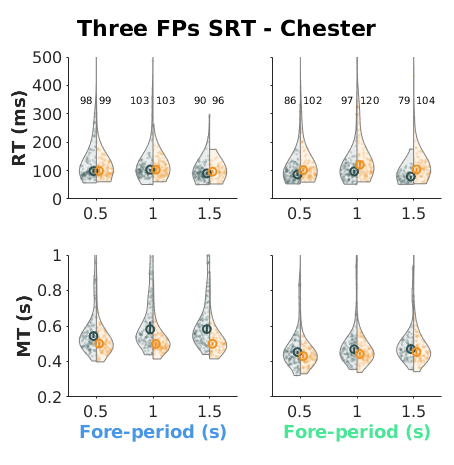

fig_response = figure(32); clf(fig_response);
set(fig_response, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 8.2], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_response, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_w = 3; ax_h = 2.5;
ax_w_sep = .6; ax_h_sep = 1;

ax_w_dist = ax_w + ax_w_sep;
ax_h_dist = ax_h + ax_h_sep;

ax_rt_l = axes(fig_response, "Units", "centimeters", "Position", [1.2 1.2+1*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax_rt_l, RT.Control(:,1), RT.Chemo(:,1), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1000, 'Text', true);
set(ax_rt_l, 'YLim', [0 500]);
% xlabel(ax_rt_l, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortL);
ylabel(ax_rt_l, "RT (ms)", 'FontWeight', 'bold');

ax_rt_r = axes(fig_response, "Units", "centimeters", "Position", [1.2+1*(ax_w_dist) 1.2+1*(ax_h_dist) ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax_rt_r, RT.Control(:,2), RT.Chemo(:,2), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', 1000, 'Text', true);
set(ax_rt_r, 'YLim', [0 500], 'YTickLabel', '');
% xlabel(ax_rt_r, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortR);

ax_mt_l = axes(fig_response, "Units", "centimeters", "Position", [1.2 1.2 ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax_mt_l, MT.Control(:,1), MT.Chemo(:,1), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat});
set(ax_mt_l, 'YLim', [.2 1]);
xlabel(ax_mt_l, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortL);
ylabel(ax_mt_l, "MT (s)", 'FontWeight', 'bold');

ax_mt_r = axes(fig_response, "Units", "centimeters", "Position", [1.2+1*(ax_w_dist) 1.2 ax_w ax_h], ...
    'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
plot_violin_compare(ax_mt_r, MT.Control(:,2), MT.Chemo(:,2), obj.BandWidth, ...
    'cate_name', string(obj.MixedFP), 'Color', {GPSColor.Control, GPSColor.Treat});
set(ax_mt_r, 'YLim', [.2 1], 'YTickLabel', '');
xlabel(ax_mt_r, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.PortR);

fig_name = sprintf("Test_%s_Response_SRT_%s", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_response, fig_path+".jpg", 'Resolution', 1200);
exportgraphics(fig_response, fig_path+".pdf", 'ContentType', 'vector');

function show_trials(ax, data, varargin)

defaultColor = [0 0 0];
defaultSize = 16;
defaultNumShow = 20;
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addOptional(p,'n_show', defaultNumShow, @isnumeric);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'FaceColor', defaultColor);
addParameter(p,'MarkerColor', defaultColor);
addParameter(p,'MarkerSize', defaultSize);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
n_show = p.Results.n_show;
FP = p.Results.FP;
FaceColor = p.Results.FaceColor;
MarkerColor = p.Results.MarkerColor;
MarkerSize = p.Results.MarkerSize;

%
n_show = min([n_show min(cellfun(@(x) length(x), data))]);

for i=1:length(data)
    if FP(i)~=0
        fill(ax, [0 FP(i) FP(i) 0], [0 0 1 1]+i-1, 'r', ...
            'FaceColor', FaceColor, 'FaceAlpha', .6*FP(i)/max(FP), 'EdgeColor', 'none');
    end
    id_show = randperm(length(data{i}), n_show);
    scatter(ax, data{i}(id_show), linspace(.1, .9, n_show)+i-1, MarkerSize, "filled", ...
        "MarkerEdgeColor", "none", "MarkerFaceColor", MarkerColor, "MarkerFaceAlpha", .6);
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_distr(ax, data, varargin)

defaultColor = [0 0 0];
defaultLw = repmat(1.2, 1, length(data));
defaultLs = repmat("-", 1, length(data));
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'Color', defaultColor);
addParameter(p,'LineWidth', defaultLw, @isvector);
addParameter(p,'LineStyle', defaultLs, @isvector);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
FP = p.Results.FP;
Color = p.Results.Color;
LineWidth = p.Results.LineWidth;
LineStyle = p.Results.LineStyle;

if length(LineWidth)==1
    LineWidth = repmat(LineWidth, 1, length(data));
elseif length(LineWidth)~=length(data)
    error("Unmatched length between lw and data");
end
if length(LineStyle)==1
    LineWidth = repmat(LineStyle, 1, length(data));
elseif length(LineStyle)~=length(data)
    error("Unmatched length between ls and data");
end
%

for i=1:length(data)
    if FP(i)~=0
        xline(ax, FP(i), 'LineStyle', LineStyle(i), 'Color', [.5 .5 .5]);
    end
    if ~isempty(data{i}.ci)
        fill(ax, [data{i}.x flip(data{i}.x)], [data{i}.ci(1,:) flip(data{i}.ci(2,:))], 'r', ...
            'FaceColor', Color, 'FaceAlpha', .4, 'EdgeColor', 'none');
    end
    plot(ax, data{i}.x, data{i}.f, 'Color', Color, 'LineWidth', LineWidth(i), 'LineStyle', LineStyle(i));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_violin_compare(ax, datain_1, datain_2, band_width, varargin)

defaultCate = string(1:length(datain_1));
defaultColor = repmat({[0 0 0]}, 1, 2);
defaultScale = 1;

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'datain_1', @iscell);
addRequired(p,'datain_2', @iscell);
addRequired(p,'band_width', @isnumeric);
addParameter(p,'cate_name', defaultCate);
addParameter(p,'Color', defaultColor);
addParameter(p,'Scale', defaultScale);
addParameter(p,'Text', false);

parse(p, ax, datain_1, datain_2, band_width, varargin{:});

ax = p.Results.ax;
datain_1 = p.Results.datain_1;
datain_2 = p.Results.datain_2;
band_width = p.Results.band_width;
cate_name = p.Results.cate_name;
Color = p.Results.Color;
Scale = p.Results.Scale;
Text = p.Results.Text;

n_data_1 = max(cellfun(@length, datain_1));
n_data_2 = max(cellfun(@length, datain_2));
n_data = max([n_data_1 n_data_2]);

if length(n_data_1)~=length(n_data_2)
    error("input data dont match");
else
    n_cate = length(datain_1);
end

%
data_1 = nan(n_data, n_cate);
data_2 = nan(n_data, n_cate);

for i = 1:3
    data_1(1:length(datain_1{i}), i) = Scale*datain_1{i};
    data_2(1:length(datain_2{i}), i) = Scale*datain_2{i};
end

data_med_ci_1 = bootci(1000, @(x) median(x, 'omitnan'), data_1);
data_med_ci_2 = bootci(1000, @(x) median(x, 'omitnan'), data_2);

data_med_1 = median(data_1, 'omitnan');
data_med_2 = median(data_2, 'omitnan');

%
axes(ax);
v = violinplot({data_2, data_1}, cate_name, ...
    'ViolinColor', Color([2 1]), 'ViolinAlpha', {.1, .1}, ...
    'BandWidth', Scale*band_width, 'MarkerSize', 2, ...
    'ShowMedian', false, 'ShowWhiskers', false, 'ShowBox', false);
xlim(ax, [.5 n_cate+.5]);

for i = 1:3
    v(i).ScatterPlot.MarkerFaceAlpha = .2;
    v(i).ScatterPlot2.MarkerFaceAlpha = .2;

    scatter(ax, i-.05, data_med_1(i), 16, Color{1}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    scatter(ax, i+.05, data_med_2(i), 16, Color{2}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    plot(ax, [i-.05 i-.05], data_med_ci_1(:,i), 'Color', Color{1}, 'LineWidth', 1);
    plot(ax, [i+.05 i+.05], data_med_ci_2(:,i), 'Color', Color{2}, 'LineWidth', 1);

    if Text
        text(ax, i-.05, 350, sprintf('%.0f', data_med_1(i)), 'FontSize', 5, 'HorizontalAlignment', 'right');
        text(ax, i+.05, 350, sprintf('%.0f', data_med_2(i)), 'FontSize', 5, 'HorizontalAlignment', 'left');
    end
    set(ax, 'Box', 'off');
end

end
